# ADCS Course Project

Dillon Allen

## Scenario

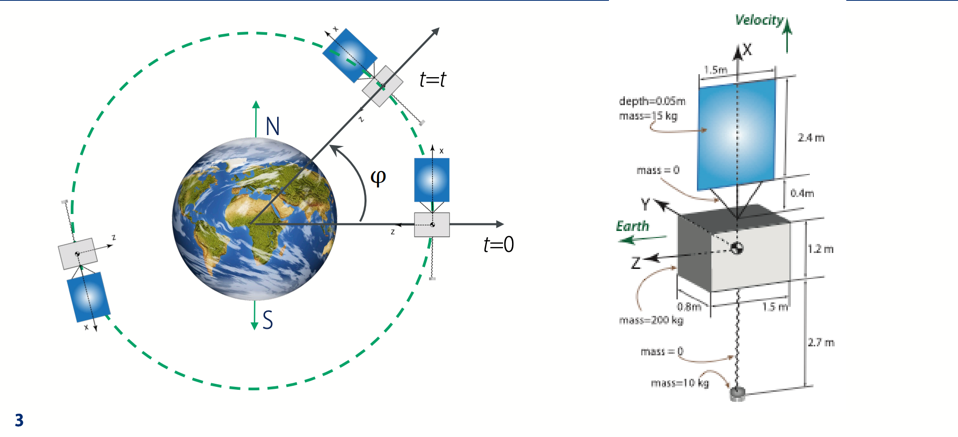

## 750 km sun-synchronous circular orbit. Inclination is $98.4^{\circ}$ and RAAN = $90^{\circ}$.

## Principle Inertias, CM is geometric center, Sun is facing -Y. +X has the solar panel, instrument on -X. Instrument is considered a point mass.

## Problem 1

### Calculate the period of the orbit, given 750 km circular.

The formula we will use is:

#### 
$$P = 2 \pi \sqrt{\frac{a^3}{\mu}}$$


mu = 3.986004356E5 % km^3/s^2

mu = 3.9860e+05

rE = 6378.14 % km

rE = 6.3781e+03

r_orbit = 750 % km

r_orbit = 750

a = rE + r_orbit

a = 7.1281e+03

P = 2*pi*sqrt(a^3/mu) % seconds

P = 5.9893e+03

P_min = P/60 % min

P_min = 99.8215

## Problem 2

### Calculate the Orbital Rate

The orbital rate, $\omega_0$, is given by

#### 
$$\omega_0 = \frac{2 \pi}{P}$$


orbitalRate = 2 * pi / P % rad/s

orbitalRate = 0.0010

## Problem 3-5

### Use STK to generate latitude over time, plot

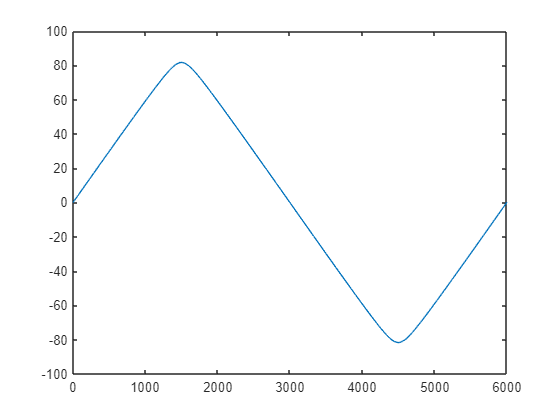

M = csvread("Satellite3_LLA_Position_1Period_1s.csv",1,1);
timeCol = 0:1:length(M)-1;
lat = M(:,1);
plot(timeCol, lat)

## Problem 6

### Show that the disturbance torque due to drag is zero

Consider the figure shown at the beginning of the document. The velocity facing side (X - axis) of the satellite can be considered symmetric due to both components lying in the X axis and the CM being the geometric center. With no protruding parts or anti-symmetric properties in the velocity face, all the drag force cross-products for the torque will cancel out. 

Considering the CM as our origin, let 

#### 
$$\textbf{r}_{i,+} = (x_i, y_i, z_i)$$


and its symmetric counterpart

#### 
$$\textbf{r}_{i,-} = (-x_i, -y_i, -z_i)$$


The velocity vector is 

#### 
$$v = - v_0 \hat{x}$$


The torque due to drag is

#### 
$$N_{\text{aero}} = - \frac{1}{2} C_{D} \rho \sum_{i} A_{i} \left[ \left(r_{i,+} \times v \right) + \left(r_{i,-} \times v \right) \right]$$


Note that

#### 
$$r_{i,+} \times v = - \left( r_{i,-} \times v\right)$$


#### 
$$N_\text{aero} = 0$$


## Problem 7

### Calculate the Solar Pressure Disturbance Torque as a function of time for one orbit

### $F_e = 1350$ W/m^2, $C_a = 0.7$, $C_d = 0.15$, $\theta = 0$, $\hat{S} = \hat{n}$

First, we will calculate the location of the center of mass, and make that our origin.

r_cm = [1.2/2, 0.8/2, 1.5/2] % m

r_cm =     0.6000    0.4000    0.7500


Next, we will assume the rectangular plane surface of the solar panel is in line with the geometric center, so the only translation is the $x$ coordinate

sp_surfaceCM = [2.4/2, 0.8/2, 1.5/2] % m

sp_surfaceCM =     1.2000    0.4000    0.7500


r_cmToSP = (sp_surfaceCM + [0.4,0,0]) - r_cm % m

r_cmToSP =      1     0     0


Now we will input our constants and calculate the solar force and torque

% Constants
Fe = 1350; Ca = 0.7; Cd = 0.15; c = 3.00E8; thetaSolar = 0; % m/s^2
Cs = 1 - Ca - Cd

Cs = 0.1500

A = 1.5 * 2.4 % m^2

A = 3.6000

The force for the solar pressure is

#### 
$$\vec{F}_{solar} = - \frac{F_e}{c} A \cos(\theta) \left[ \left(1 - C_s \right) \hat{S} + 2 \left(C_s \cos(\theta) + \frac{1}{3} C_d \right) \hat{N} \right]$$


solarForce = -(Fe/c)*A*cos(thetaSolar)*((1-Cs) + ...
    2*(Cs*cos(thetaSolar) + (1/3)*Cd)) .* [0 -1 0]

solarForce = 	1.0e+-4 *

         0    0.2025         0


solarDisturbanceTorque = cross(r_cmToSP, solarForce)

solarDisturbanceTorque = 	1.0e+-4 *

         0         0    0.2025


Since the geometry of the orbit is always in the $x-z$ plane, the torque will be constant throughout the orbit over time.

## Problem 9

### Calculate the disturbance due to residual magnetic torque

For here, we will use the simplified dipole equation

#### 
$$B_r = - \frac{2B_0}{R^3} \sin \lambda$$


#### 
$$B_\lambda = \frac{B_0}{R^3} \cos \lambda$$


where $B_0 = 31,200$nT. 

The torque will be

#### 
$$\vec{N}_{mag} = \vec{m} \times \left( B_{\lambda} \hat{x} + 0 \hat{y} + B_{r} \hat{z} \right)$$


This will vary over time, so $\lambda = \omega_0 t$, where $t \in [0, P]$

B0 = 31200E-9; % Teslas
m_dipole = 1; % A-T-m^2
m_dipole_vec = m_dipole .* [0 -1 0]

m_dipole_vec =      0    -1     0


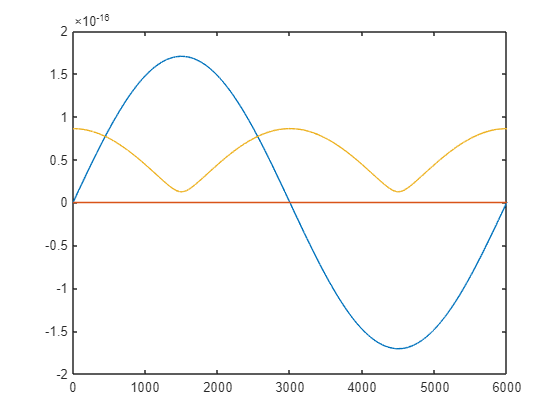

% for t = 0:1:P
%     idx = t+1;
%     Bz(idx) = (-2*B0/a^3)*sin(orbitalRate*(t));
%     By(idx) = 0;
%     Bx(idx) = (B0/a^3)*cos(orbitalRate*(t));
%     MagTorque(idx,:) = cross(m_dipole_vec, [Bx(idx), By(idx), Bz(idx)]);
% end

Bz = (-2*B0/a^3)*sind(lat);
By = zeros(size(lat));
Bx = (B0/a^3)*cosd(lat);
Bfield = [Bx By Bz];
rep_mag = repmat(m_dipole_vec,length(lat),1);
magField = cross(rep_mag, Bfield );
fieldTime = 0:1:length(magField)-1;
plot(fieldTime, magField);

## Problem 10

### Plot the two disturbance torques and the total over the period of one orbit

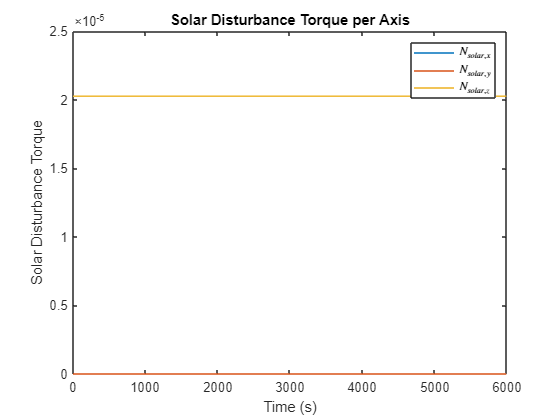

% time vector
timeVec = 0:1:P;

% Solar Disturbance Torque
solarX = solarDisturbanceTorque(1)*ones(1,length(timeVec));
solarY = solarDisturbanceTorque(2)*ones(1,length(timeVec));
solarZ = solarDisturbanceTorque(3)*ones(1,length(timeVec));
figure('Name', 'Solar Disturbance Torque')
plot(timeVec, solarX)
hold on
plot(timeVec, solarY)
plot(timeVec, solarZ)
xlabel("Time (s)")
ylabel("Solar Disturbance Torque")  
title("Solar Disturbance Torque per Axis")
legend("$N_{solar, x}$", "$N_{solar,y}$", "$N_{solar,z}$", 'Interpreter', 'Latex')


% Magnetic Disturbance Torque
magX = MagTorque(:,1);

Unrecognized function or variable 'MagTorque'.

magY = MagTorque(:,2);
magZ = MagTorque(:,3);
figure('Name', 'Magnetic Disturbance Torque')
plot(timeVec, magX)
hold on
plot(timeVec, magY)
plot(timeVec, magZ)
xlabel("Time (s)")
ylabel("$N_{mag}$", 'Interpreter', 'latex');
legend('$N_{mag,x}$', '$N_{mag,y}$', '$N_{mag,z}$', 'Interpreter', 'latex')

% total disturbance
xDisturbance = solarX + magX';
yDisturbance = solarY + magY';
zDisturbance = solarZ + magZ';

figure('Name', 'Total Disturbance Torque');
plot(timeVec, xDisturbance)
hold on
plot(timeVec, yDisturbance)
plot(zDisturbance)
xlabel("Time (s)")
ylabel("Total Disturbance")
legend("$N_{tot,x}$", "$N_{tot,y}$", "$N_{tot,z}$", 'Interpreter', 'latex')

## Problem 11

### What is the peak momentum over one orbit along the three axes?

For this, we can use the max value function for each disturbance. The $\Delta t = 1$ second, so the momentum is $N \Delta t = N \times 1$.

peakX = max(xDisturbance)
peakY = max(yDisturbance)
peakZ = max(zDisturbance)

## Problem 12

### What is the momentum change over the orbit along the three axes?

we can separate the first order differential equation to find momentum, i.e

#### 
$$\int_{p_0}^{p_f} dp = \int_{t_0}^{t_f} N \ dt$$


#### 
$$\Delta p = \int_{t_0}^{t_f} N \ dt$$


dp_x = trapz(xDisturbance)
dp_y = trapz(yDisturbance)
dp_z = trapz(zDisturbance)

## ADCS Project Part 2

## Problem 13

## Problem 14

### Find the Interia of the wheels

#### 
$$h_{max} = I \omega_{max}$$


% wheel parameters
Tw_max    = 0.025; % N-m
hw_max    = 0.5;   % N-m-s
omega_max = 6000;  % rpm

% Convert RPM to rad/s
omega_max_rps = 6000 * 2 * pi / 60; % rad/s

I_wheel = hw_max / omega_max_rps % N-m

## Problem 15

### Find the max acceleration due to the wheel along X-axis, Y-axis, Z-axis